# Spectral Estimation: ARMA-Octave bands

*Autoregressive, Moving-average filters for estimation of the power spectrum of White Gaussian Noise*

**ARMA = Autoregressive Moving-Average**

**Configurate the path and clear the workspace, etc.**

clc; close all; clear;
addpath(genpath(fullfile('../')));

## **Augmentation and spectral estimation**

***Select order of AR and MA model:***

p = 12;
q = 12;

***Select IR set for augmentation:***

nameIRms = "IR44K_2s_1000ms";

fs = 44100;
IRLen = 40;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth
IRms = struct2cell(load(dir+nameIRms));
IRms = IRms{1};
IRms =IRms(:,2);
IRms = [IRms{:}];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%               Prepare Bands           %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Calculate Third Octave Bands (base 2) 
octaves = 3;
N_bands = ceil(32*(octaves/3));
bands = zeros(N_bands,3);
start_band =floor(18*(octaves/3));
end_band = N_bands-start_band-1;
bands(:,2)  = 10^3 * (2 .^ ([-start_band:end_band]/octaves));
fd = 2^(1/(octaves*2));
bands(:,3) = bands(:,2).* fd;
bands(:,1) = bands(:,2) ./ fd;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

nfft = 8192;
N_bins = N_bands;
df = fs/(2*((nfft/2)+1));
f = 0:df:(fs-df)/2;
f_2_5k = ceil(2500/(fs/(N_bins*2)));
f_20k = ceil(20000/(fs/(N_bins*2)));


N_noise_samples = 10;
N_augmentations = N_noise_samples*IRLen;% 100 noise samples * 40 augmentations = 4000 augmented samples

noise_aug_psd_reverb = zeros(N_bins,N_augmentations);
labels_reverb = zeros(N_augmentations,1);
vec = [1:6, 36:40; 6:16; 16:26; 26:36];
for k = 1:N_noise_samples
    for i = 1:40
        % Augment noise sample
        noise = randn(fs,1);
        index = ((k-1)*40) + i;
        noise_aug = conv(noise, IRms(:,i), 'same');
       
        Pxx = arma_power_est(noise_aug,p,q,nfft,fs);
        Pxx = normalize(Pxx,'range');
        
        for t = 1:N_bands
            noise_aug_psd_reverb(t,index) = mean(Pxx(f>= bands(t,1) & f <= bands(t,3)));    % Band-average without window
        end
        labels_reverb(index) = i;
    end
end

## Example of PSD

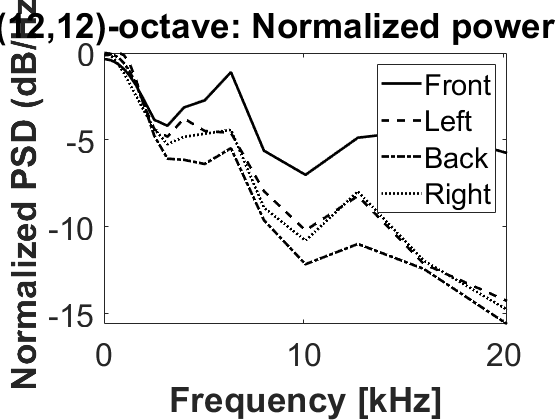

figure;
line = ["-", "--", "-.", ":"];
plot(bands(:,2)/1000, 10*log10(noise_aug_psd_reverb(:,1)),'k',"LineStyle",line(1),"LineWidth",2); hold on;
plot(bands(:,2)/1000, 10*log10(noise_aug_psd_reverb(:,11)),'k',"LineStyle",line(2),"LineWidth",2); hold on;
plot(bands(:,2)/1000, 10*log10(noise_aug_psd_reverb(:,21)),'k',"LineStyle",line(3),"LineWidth",2); hold on;
plot(bands(:,2)/1000, 10*log10(noise_aug_psd_reverb(:,31)),'k',"LineStyle",line(4),"LineWidth",2); hold on;
title("ARMA(" + p+","+q+")-octave: Normalized power spectrum",'FontSize',48);
xlabel("Frequency [kHz]",'FontSize',18,'FontWeight',"bold"); ylabel("Normalized PSD (dB/Hz)",'FontSize',24,'FontWeight',"bold");
legend("Front","Left", "Back", "Right");
ax = gca;
ax.FontSize = 24;

## **Probability Density functions of four direction: Front, Left, Back, Right**

Pyy_set_front = noise_aug_psd_reverb(:,ismember(labels_reverb,vec(1,:)));
Pyy_set_left = noise_aug_psd_reverb(:,ismember(labels_reverb,vec(2,:)));
Pyy_set_back = noise_aug_psd_reverb(:,ismember(labels_reverb,vec(3,:)));
Pyy_set_right = noise_aug_psd_reverb(:,ismember(labels_reverb,vec(4,:)));

***make pdfs of relative power at frequency (w) ***

*These are our prior distributions*

N = size(vec,2)*N_augmentations/40;
mean_front = sum(Pyy_set_front,2)/N;
standard_deviation_front = sqrt(sum((Pyy_set_front-mean_front).^2, 2)/N);
pdf_front = zeros(size(Pyy_set_front));
pdf_front_normalized = zeros(size(Pyy_set_front));

mean_left = sum(Pyy_set_left,2)/N;
standard_deviation_left = sqrt(sum((Pyy_set_left-mean_left).^2, 2)/N);
pdf_left = zeros(size(Pyy_set_left));
pdf_left_normalized = zeros(size(Pyy_set_left));

mean_back = sum(Pyy_set_back,2)/N;
standard_deviation_back = sqrt(sum((Pyy_set_back-mean_back).^2, 2)/N);
pdf_back = zeros(size(Pyy_set_back));
pdf_back_normalized = zeros(size(Pyy_set_back));

mean_right = sum(Pyy_set_right,2)/N;
standard_deviation_right = sqrt(sum((Pyy_set_right-mean_right).^2, 2)/N);
pdf_right = zeros(size(Pyy_set_right));
pdf_right_normalized = zeros(size(Pyy_set_right));

% Assumed normal distribution
for i = 1:N_bins
    pdf_front(i,:) = normpdf(Pyy_set_front(i,:),mean_front(i),standard_deviation_front(i));
    pdf_left(i,:) = normpdf(Pyy_set_left(i,:),mean_left(i),standard_deviation_left(i));
    pdf_back(i,:) = normpdf(Pyy_set_back(i,:),mean_back(i),standard_deviation_back(i));
    pdf_right(i,:) = normpdf(Pyy_set_right(i,:),mean_right(i),standard_deviation_right(i));
    
    pdf_front_normalized(i,:) = normalize(pdf_front(i,:),'range');
    pdf_left_normalized(i,:) = normalize(pdf_left(i,:), 'range');
    pdf_back_normalized(i,:) = normalize(pdf_back(i,:), 'range');
    pdf_right_normalized(i,:) = normalize(pdf_right(i,:), 'range');
end

## PDF visualization

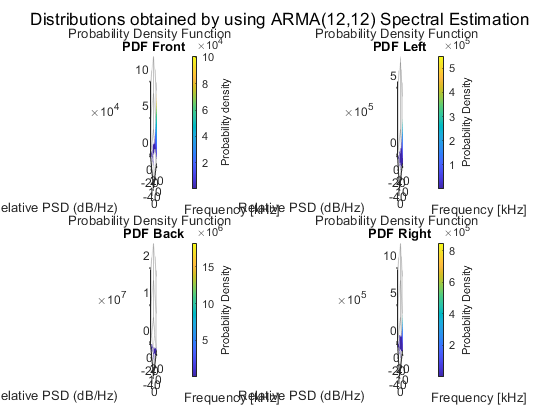

%   X: Relative dB
%   Y: Frequency
%   Z: Probability Density Function

X = repmat(bands(:,2)/1000,1,N);
Y = 10*log10(Pyy_set_front);
Z = pdf_front;
figure;
subplot(2,2,1);surf(X,Y,Z);
C = colorbar;
ylabel(C,'Probability density');
ylim([-50, 0]);
shading interp
xlabel("Frequency [kHz]"); ylabel("Relative PSD (dB/Hz)"); zlabel("Probability Density Function"); title("PDF Front");
X = repmat(bands(:,2)/1000,1,N);
Y = 10*log10(Pyy_set_left);
Z = pdf_left;
subplot(2,2,2); surf(X,Y,Z);
C = colorbar;
ylabel(C,'Probability Density');
ylim([-50, 0]);
shading interp
xlabel("Frequency [kHz]"); ylabel("Relative PSD (dB/Hz)"); zlabel("Probability Density Function"); title("PDF Left");
X = repmat(bands(:,2)/1000,1,N);
Y = 10*log10(Pyy_set_back);
Z = pdf_back;
subplot(2,2,3); surf(X,Y,Z);
C = colorbar;
ylabel(C,'Probability Density');
ylim([-50, 0]);
shading interp
xlabel("Frequency [kHz]"); ylabel("Relative PSD (dB/Hz)"); zlabel("Probability Density Function"); title("PDF Back");
X = repmat(bands(:,2)/1000,1,N);
Y = 10*log10(Pyy_set_right);
Z = pdf_right;
subplot(2,2,4); surf(X,Y,Z);
C = colorbar;
ylabel(C, "Probability Density");
ylim([-50, 0]);
shading interp
xlabel("Frequency [kHz]"); ylabel("Relative PSD (dB/Hz)"); zlabel("Probability Density Function"); title("PDF Right");
sgtitle("Distributions obtained by using ARMA("+ p+"," +q+") Spectral Estimation");

## Normalized PDF visualization

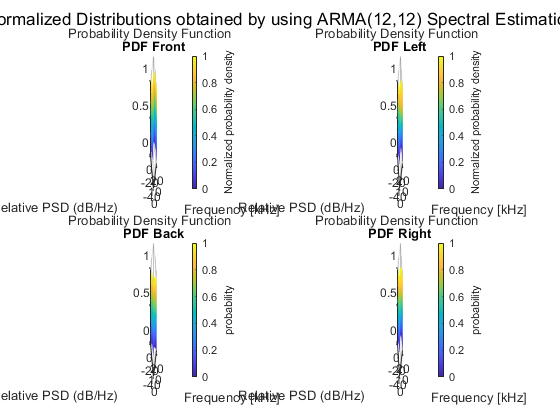

%   X: Relative dB
%   Y: Frequency
%   Z: Probability Density Function

X = repmat(bands(:,2)/1000,1,N);
Y = 10*log10(Pyy_set_front);
Z = pdf_front_normalized;
figure;
subplot(2,2,1);surf(X,Y,Z);
C = colorbar;
ylabel(C,'Normalized probability density');
ylim([-50, 0]);
shading interp
xlabel("Frequency [kHz]"); ylabel("Relative PSD (dB/Hz)"); zlabel("Probability Density Function"); title("PDF Front");
X = repmat(bands(:,2)/1000,1,N);
Y = 10*log10(Pyy_set_left);
Z = pdf_left_normalized;
subplot(2,2,2); surf(X,Y,Z);
C = colorbar;
ylabel(C,'Normalized probability density');
ylim([-50, 0]);
shading interp
xlabel("Frequency [kHz]"); ylabel("Relative PSD (dB/Hz)"); zlabel("Probability Density Function"); title("PDF Left");
X = repmat(bands(:,2)/1000,1,N);
Y = 10*log10(Pyy_set_back);
Z = pdf_back_normalized;
subplot(2,2,3); surf(X,Y,Z);
C = colorbar;
ylabel(C,'probability');
ylim([-50, 0]);
shading interp
xlabel("Frequency [kHz]"); ylabel("Relative PSD (dB/Hz)"); zlabel("Probability Density Function"); title("PDF Back");
X = repmat(bands(:,2)/1000,1,N);
Y = 10*log10(Pyy_set_right);
Z = pdf_right_normalized;
subplot(2,2,4); surf(X,Y,Z);
C = colorbar;
ylabel(C, "probability");
ylim([-50, 0]);
shading interp
xlabel("Frequency [kHz]"); ylabel("Relative PSD (dB/Hz)"); zlabel("Probability Density Function"); title("PDF Right");
sgtitle("Normalized Distributions obtained by using ARMA("+ p+"," +q+") Spectral Estimation");

## Most likely Power spectrum for each direction 

*We take the highest pdf value at each frequency bin to form the most likely representation for each direction*

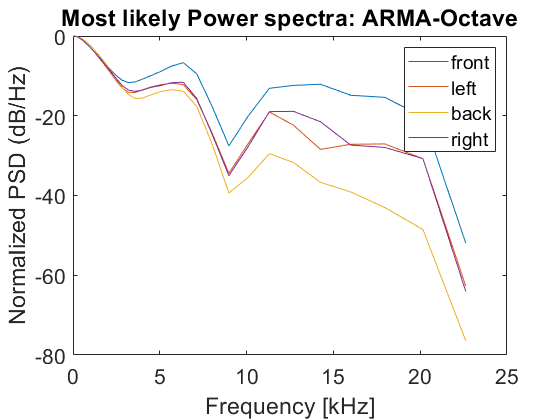

pyy_max = zeros(N_bins,4);
for i = 1:N_bins
    [val,idx] = max(pdf_front(i,:));
    pyy_max(i,1) = Pyy_set_front(i,idx);
    
    [val,idx] = max(pdf_left(i,:));
    pyy_max(i,2) = Pyy_set_left(i,idx);
    
    [val,idx] = max(pdf_back(i,:));
    pyy_max(i,3) = Pyy_set_back(i,idx);
    
    [val,idx] = max(pdf_right(i,:));
    pyy_max(i,4) = Pyy_set_right(i,idx);
end
figure;
for i = 1:4
    plot(bands(:,2)/1000, 10*log10(pyy_max(:,i))); hold on;
end
title("Most likely Power spectra: ARMA-Octave", "FontSize",32);
xlabel("Frequency [kHz]"); ylabel("Normalized PSD (dB/Hz)");
legend("front","left","back","right");
ax = gca;
ax.FontSize = 16;